### Spatial and Temporal Plots for $\epsilon$

% Spacial variations

L = 1e-2;
N_L = 100;
mu_0 = pi*4e-7;
eps_0 = 8.85418782e-12;
omega = 2*pi*(10^(10));
Z_L = 0.7*1e2;
vp = 0.5e8;
z = linspace(0, L, N_L);

k = omega/vp;

% we use a chebyshev's Low Pass Filter

kc = k; % cutoff
ks = k*1e2; % sampling freq
rp = 1; % ripple

% Calculate analog cutoff frequency and convert to digital
% wc = 2*pi*kc; % analog cutoff frequency
% wd = 2*pi*kc/ks; % digital cutoff frequency
kd = kc/ks;

% Design Chebyshev Type I filter coefficients
[n, Wn] = cheb1ord(kd, 0.5*kd, rp, 60);
[bc, ac] = cheby1(n, rp, Wn);

% take delta function as input
x = [1, zeros(1, N_L-1)];

Gamma = filter(bc, ac, x); % Gamma(z)
[Hz, w] = freqz(bc, ac, N_L); % freq resp

dGamma = gradient(Gamma); % Gamma'(z)

% find a and b
a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(L/N_L) - trapz(a)*(L/N_L);

% Calculate I(z)
I = exp(-int_a);
D = cumtrapz(I.*b)*(L/N_L) - trapz(I.*b)*(L/N_L);

% find eps(z)
epsz = ( I(N_L)*(Z_L/sqrt(mu_0))*I.^(-1) + I.^(-1).*D ).^(-2);

disp(epsz)

   1.0e-09 *

   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.0000i   0.2565 + 0.000

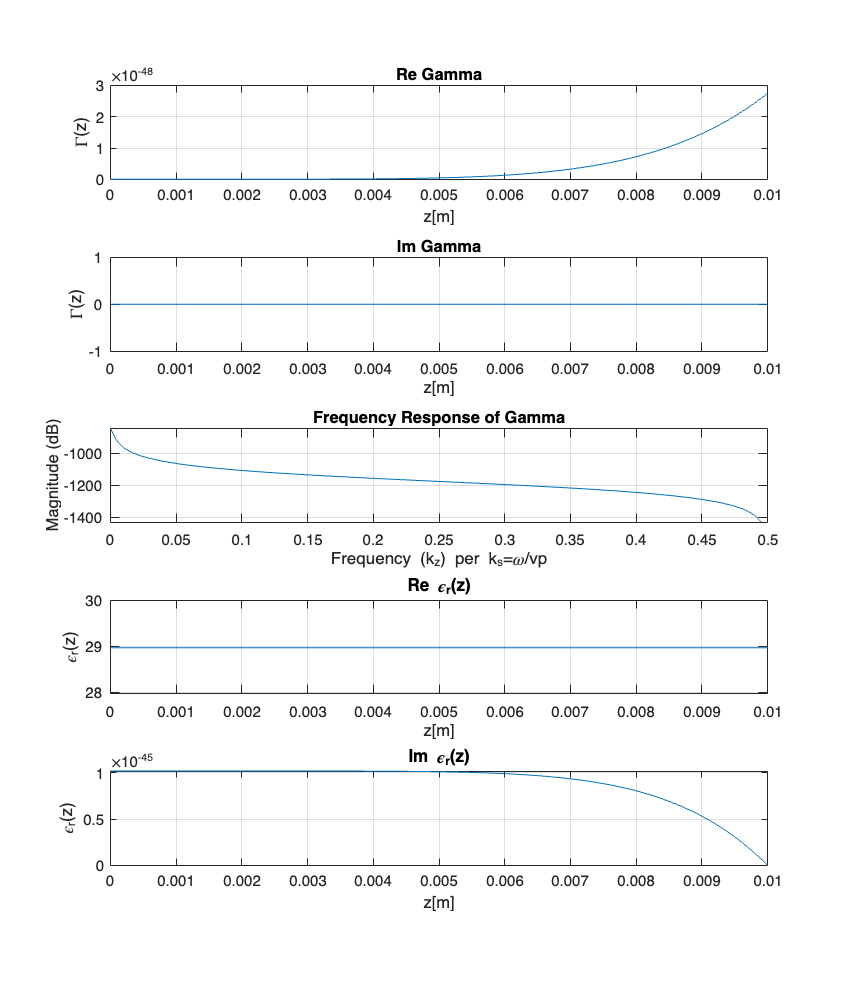


figure1=figure('Position', [100, 100, 1024, 1200]);
subplot(5,1,1)
plot(z, real(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("Re Gamma")

subplot(5,1,2)
plot(z, imag(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("Im Gamma")

subplot(5,1,3)
plot(w/(2*pi), 20*log10(abs(Hz)));
xlabel('Frequency (k_z) per k_z_s=\omega/vp');
ylabel('Magnitude (dB)');
grid("on")
title('Frequency Response of Gamma');

subplot(5,1,4)
plot(z, real(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Re \epsilon_r(z)")

subplot(5,1,5)
plot(z, imag(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Im \epsilon_r(z)")

Temporal change

clear Gamma dGamma
T = 1e-9;
N_T = 100;
t = linspace(0, T, N_T);

% we use a chebyshev's Low Pass Filter

fc = 5*omega/1e2; % cutoff frequency
fs = omega*10; % sampling freq
rp = 1; % ripple

% Calculate analog cutoff frequency and convert to digital
wc = 2*pi*fc; % analog cutoff frequency
wd = 2*pi*fc/fs; % digital cutoff frequency

% Design Chebyshev Type I filter coefficients
[n, Wn] = cheb1ord(wd, 0.5*wd, rp, 60);
[bc, ac] = cheby1(n, rp, Wn);

% take delta function as input so that output will give Gamma(t)
x = [1, zeros(1, N_L-1)];

Gamma = filter(bc, ac, x); % Gamma(z)
[Ht, w] = freqz(bc, ac, N_T); % freq resp

dGamma = gradient(Gamma); % Gamma'(z)


a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(T/N_T) - cumtrapz(a(1))*(T/N_T);

% Calculate I(z)
I = exp(int_a);

D = cumtrapz(I.*b)*(T/N_T) - cumtrapz(I(1)*b(1))*(T/N_T);
epst = ( I(1)*(1/(5*sqrt(eps_0)))*I.^(-1) - I.^(-1).*D ).^(-2);

disp(epst)

   1.0e-09 *

   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.000

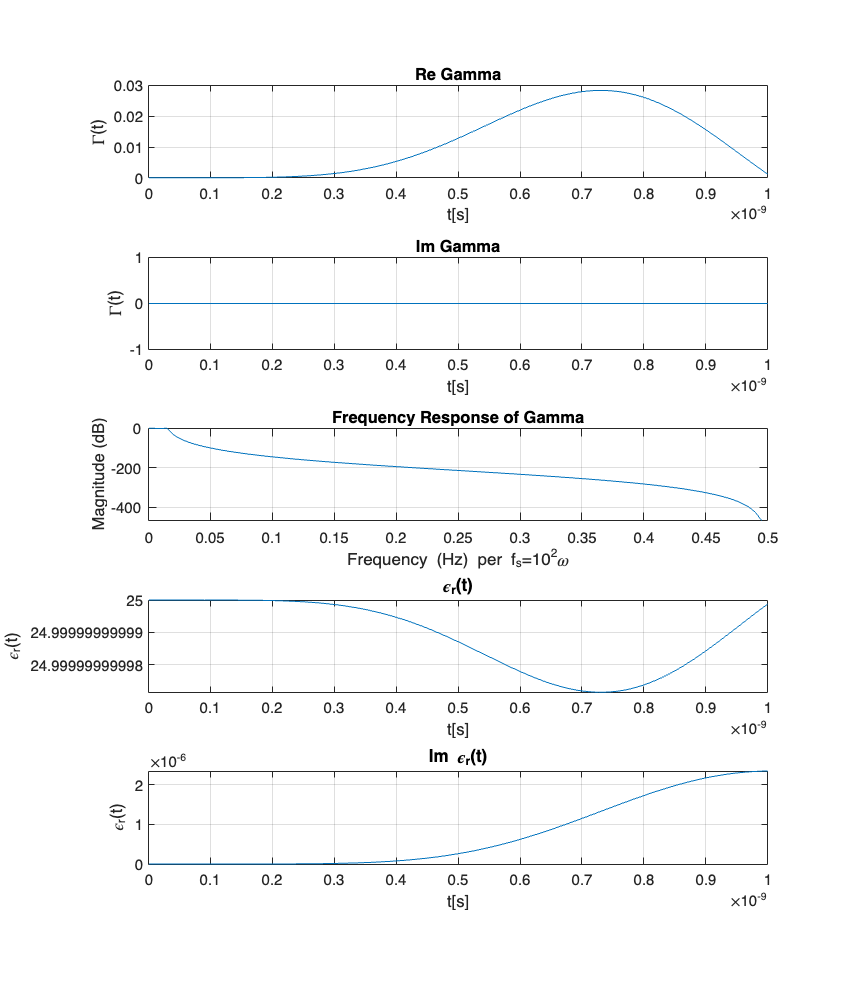


figure2=figure('Position', [100, 100, 1024, 1200]);
subplot(5,1,1)
plot(t, real(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("Re Gamma")

subplot(5,1,2)
plot(t, imag(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("Im Gamma")

subplot(5,1,3)
plot(w/(2*pi), 20*log10(abs(Ht)));
xlabel('Frequency (Hz) per f_s=10^2\omega');
ylabel('Magnitude (dB)');
grid("on")
title('Frequency Response of Gamma');

subplot(5,1,4)
plot(t, abs(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("\epsilon_r(t)")

subplot(5,1,5)
plot(t, imag(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("Im \epsilon_r(t)")

### Relating with $L$ and $C$

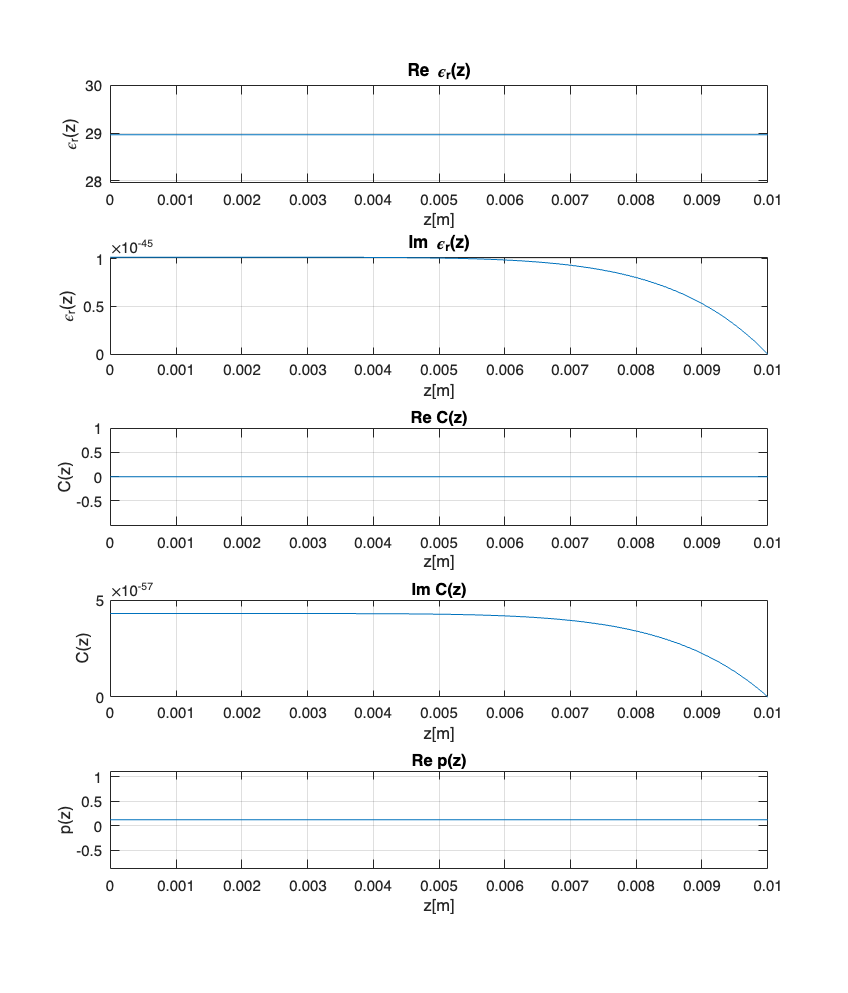

% Random values for L and C

L0 = 600e-9;

C = L0.*epsz./mu_0;

C0 = 20e-15;
Cshunt = 1e-9;

p = (C-C0)./Cshunt;

figure3=figure('Position', [100, 100, 1024, 1200]);
subplot(5,1,1)
plot(z, real(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Re \epsilon_r(z)")

subplot(5,1,2)
plot(z, imag(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Im \epsilon_r(z)")

subplot(5,1,3)
plot(z, real(C));
grid("on")
xlabel("z[m]")
ylabel("C(z)")
title("Re C(z)")

subplot(5,1,4)
plot(z, imag(C));
grid("on")
xlabel("z[m]")
ylabel("C(z)")
title("Im C(z)")

subplot(5,1,5)
plot(z, real(p));
grid("on")
xlabel("z[m]")
ylabel("p(z)")
title("Re p(z)")